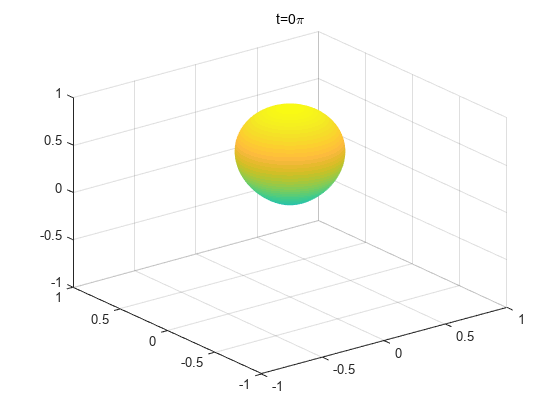

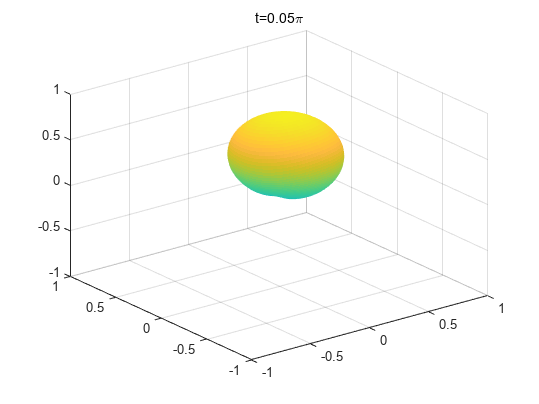

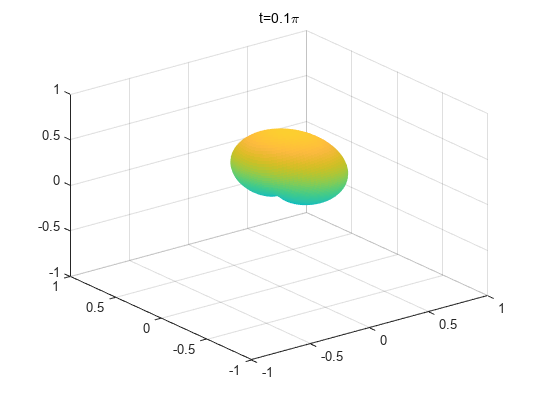

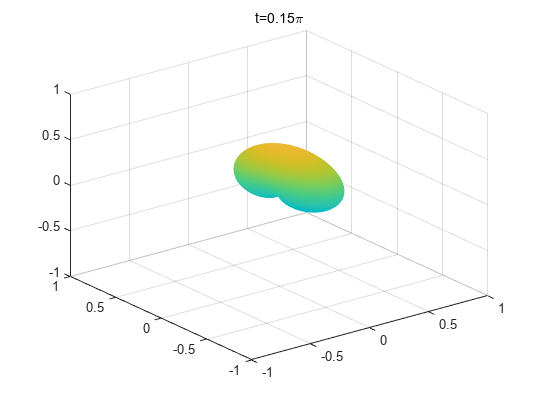

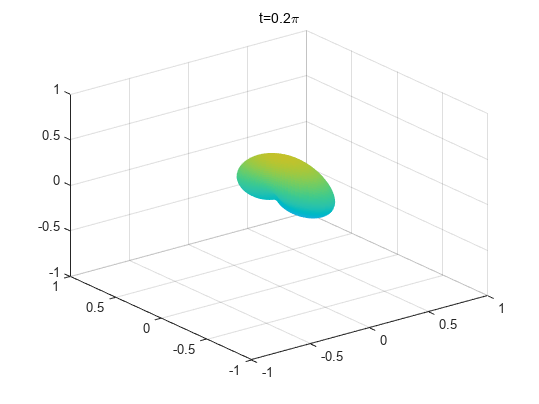

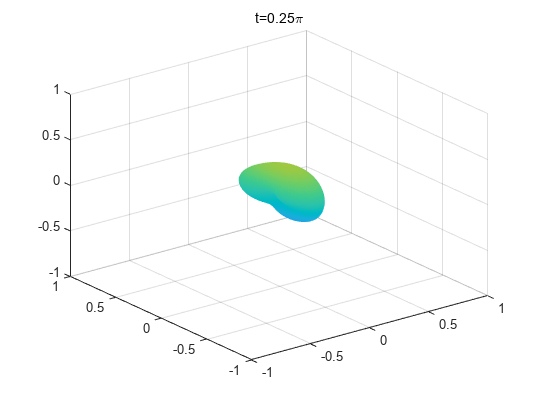

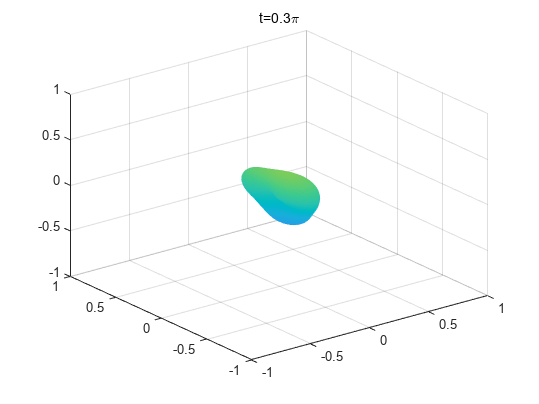

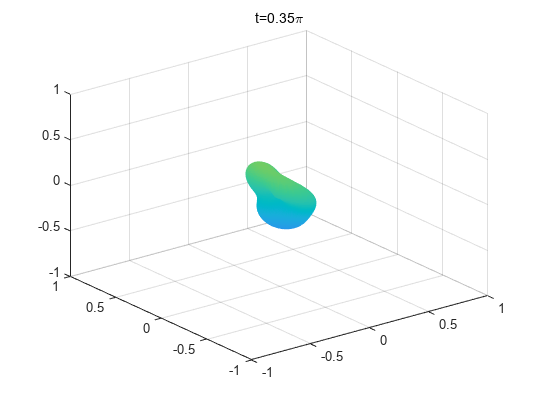

clear all;
delay=1/24; % s
precess_time_duration=[0:0.01:2]*pi;
%precess_time_duration=[0:1:pi];
sigma=0.1;
center=0.3;
filename="DFS_sphere.gif";
for i=1:length(precess_time_duration)
    precess_time=precess_time_duration(i);
    frame=oneframe(precess_time,center,sigma);
    im=frame2im(frame);
    [imind,cm]=rgb2ind(im,256);
    if i==1
        imwrite(imind,cm,filename,"gif","LoopCount",inf,"DelayTime",delay);
    else
        imwrite(imind,cm,filename,"gif","WriteMode","append","DelayTime",delay);
    end
end

function output=oneframe(precession_time,center,sigma)
sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');

scatter_number=100-1;
theta=[0:pi/scatter_number:pi];
phi=[0:2*pi/scatter_number:pi*2];
inital_state=[1 0 0 0 0 0]';
sample_num=1;
density_matrix=zeros(6,6);
for i=1:sample_num
    distribution=normrnd(center,sigma);
    ham_piover2=sigmax+sigmax^2;
    ham_precession=1*sigmaz+1*distribution.*sigmax^2;
    transverse_polar=ham_evolve(ham_piover2,inital_state,0);
    precess_state=ham_evolve(ham_piover2,transverse_polar,precession_time);

    density_matrix=precess_state*precess_state'+density_matrix;
end
density_matrix=density_matrix./sample_num;
%trace(density_matrix^2);
for i=1:length(theta)
    theta_in=theta(i);
    for j=1:length(phi)
        phi_in=phi(j);
        result(i,j)=spin_coherent(theta_in,phi_in)'*density_matrix*spin_coherent(theta_in,phi_in);
    end
end
% f1=figure;
% p=pcolor(phi,theta,abs(result));
% p.LineStyle="none";
% title(['t=',num2str(precession_time/pi),'\pi']);
% set(gca,"Clim",[0 1]);
% colormap summer;colorbar;grid off;
% drawnow;
% output=getframe(f1);
% set(f1,"Visible","Off");

f2=figure;
theta=pi/2-theta;
[theta2,phi2]=meshgrid(theta,phi);
[x,y,z]=sph2cart(phi2,theta2,abs(result)');
surf=mesh(x,y,z);
xlim([-1 1]);
zlim([-1 1]);
ylim([-1 1]);
%set(f2,"Visible","Off");
set(surf,"LineStyle","none", "FaceColor","texturemap",...
   "FaceLighting","gouraud");


set(gca,"Clim",[-1 1]);grid on;
title(['t=',num2str(precession_time/pi),'\pi']);

output=getframe(f2);
end



function state=spin_coherent(theta,phi)
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
polar=[1 0 0 0 0 0]';
state1=ham_evolve(sigmay,polar,theta);
state=ham_evolve(sigmaz,state1,phi);
end

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end